clc; clear; close all;

# Ecuaciones no lineales

Bisección

% f=@(x)x.^2+2*x-3;
% c=biseccion(f,-2,3,1e-10)

f=@(x)sqrt(x.^3.*sin(x))-log(cos(x))-3;
%fplot(g,[-20 20],'LineWidth',2)
c=biseccion(f,-6.5,-5.5,1e-10)

'biseccion' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\qweq9\OneDrive - Benemérita Universidad Autónoma de Puebla\MAIN\.UNIVERSIDAD\BUAP\5to Semestre\Análisis numérico\Matlab

Change the MATLAB current folder or add its folder to the MATLAB path.

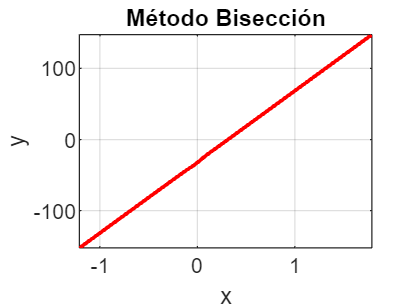

V = 0.3124

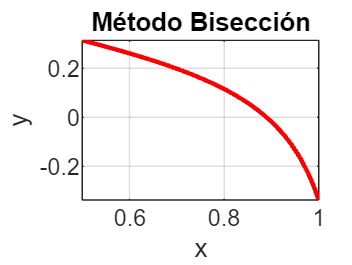

c = 0.8894

V=VanDerWaals(100,80,0.03412,0.02370)

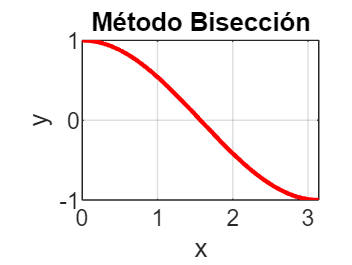

c = 1.5708

f='cos';
c=biseccioneval(f,0,pi,1e-6)

c = 1.5708

c=biseccioneval(@cos,0,pi,1e-6)

c = 1.5708

f=@(x)cos(x);
c=biseccioneval(f,0,pi,1e-6)

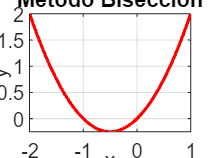

c = -1.0000

f=@(x)x.^2+x;
c=biseccioneval(f,-2,1,1e-6)

# Variables simbólicas

syms x y t
f=x^2+x;
w=subs(f,5)

$$w = 30$$

u=double(w)

u = 30

g=sin(x)-1+cos(t)+y;
g=subs(g,[x,y,t],[1 0 5])

$$g = \cos\left(5\right)+\sin\left(1\right)-1$$

h=double(g)

h = 0.1251

g=sin(x)-1+cos(t)+y

$$g = y+\cos\left(t\right)+\sin\left(x\right)-1$$

var = diff(g,x)

$$var = \cos\left(x\right)$$

# Algoritmo de Newton

La aproximación está en la tolerancia indicada


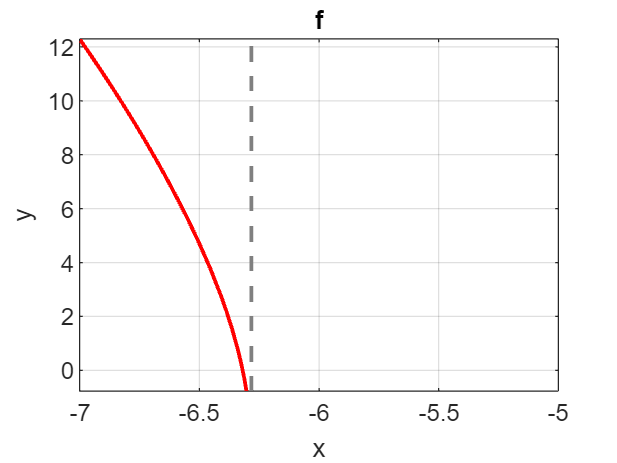

x1 =  -6.318849819081029 + 0.000000000347629i


err =      7.603316806625152e-06


syms x
format long
f=sqrt(x.^3.*sin(x))-log(cos(x))-3;
%c=biseccion(f,-6.5,-5.5,1e-10)
[x1,err]=newton1(f,-6,10,10e-6)

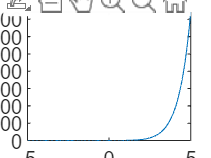

syms x
f=x.^2*exp(x);
fplot(f)

vpasolve(f)

$$ans = 0$$

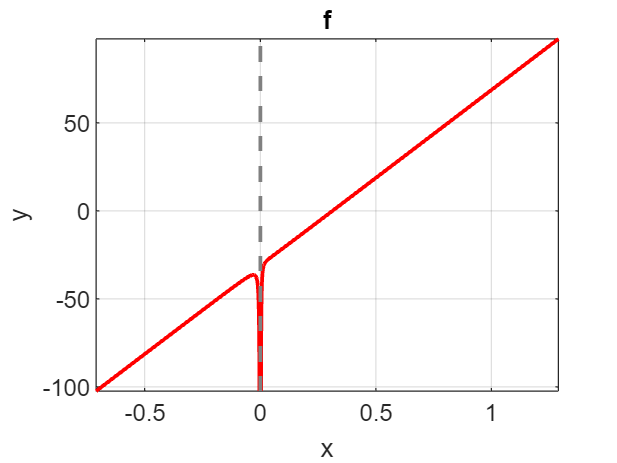

V =    0.312450393092918


err =      5.110544130992878e-06


P=100;
T=80;
a=0.03412;
b=0.02370;
T=T+273.15; % Convirtiendo T(C) a T(K)
R=0.08205; % Constante universal
syms V
f=(P+a./V.^2).*(V-b)-R*T;
V0=R*T/P; % Volumen molar ideal
%[V,err]=newton1(f,V0,2,10e-6)
[V,err]=newtonwhile(f,V0,10e-6)

SRK Equation of state

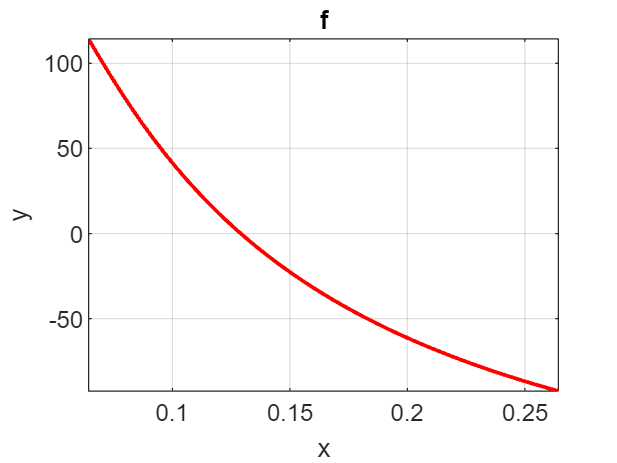

V =    0.129106912349253


err =      3.650308735836383e-07


Tc=419.6; % Temperatura crítica
Pc=40.2*9.86923; % Presión Crítica en atm
P=21*9.86923; % Presión en atm
T=415;
R=0.082054; % Constante universal de los gases
a=0.42748*((R.^2.*Tc.^(5/2))./Pc);
b=0.08664*(R.*Tc./Pc);
syms V
f=(R*T)/(V-b)-a/(V*(V+b)*sqrt(T))-P;
V0=R*T/P;
[V,err]=newtonwhile(f,V0,10e-6)

Algoritmo de la regla falsa, de la secante, del punto fijo

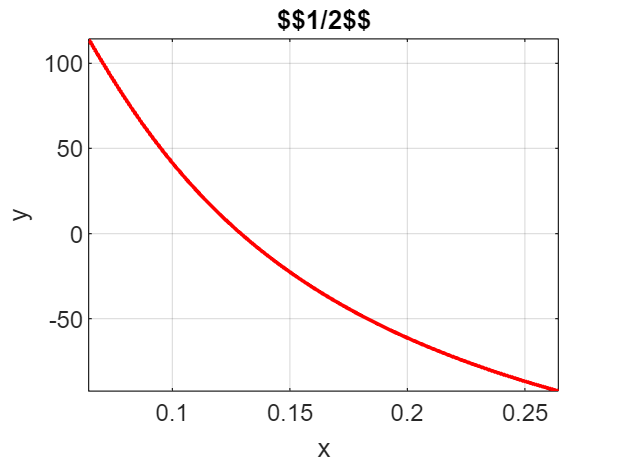

V =    0.129106912349253


err =      3.650308736113939e-07


Tc=419.6; % Temperatura crítica
Pc=40.2*9.86923; % Presión Crítica en atm
P=21*9.86923; % Presión en atm
T=415;
R=0.082054; % Constante universal de los gases
a=0.42748*((R.^2.*Tc.^(5/2))./Pc);
b=0.08664*(R.*Tc./Pc);
f=@(V)(R.*T)./(V-b)-a./(V.*(V+b).*sqrt(T))-P;
V0=R*T/P;
[V,err]=newtonwhile2(f,V0,10e-6)

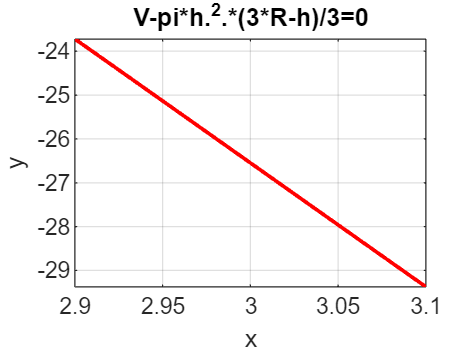

h = 2.0269

err = 2.2458e-09

R=3; %Radio del tanque (m)
V=30; %Volumen (m3)
f=@(h)V-pi*h.^2.*(3*R-h)/3; %profundidad del agua
[h,err]=newtonwhile2(f,R,10e-6)

%%


Leer string, cell, struct

2. App designer

A=-7.27084;
B=1.26113;
C=-2.81741;
D=-2.17642;
T=100;
f=@(Psat)A-B./T+C.*log(T)+D*(Psat)./(T.^2)-log(Psat)

f = function_handle with value:
    @(Psat)A-B./T+C.*log(T)+D*(Psat)./(T.^2)-log(Psat)


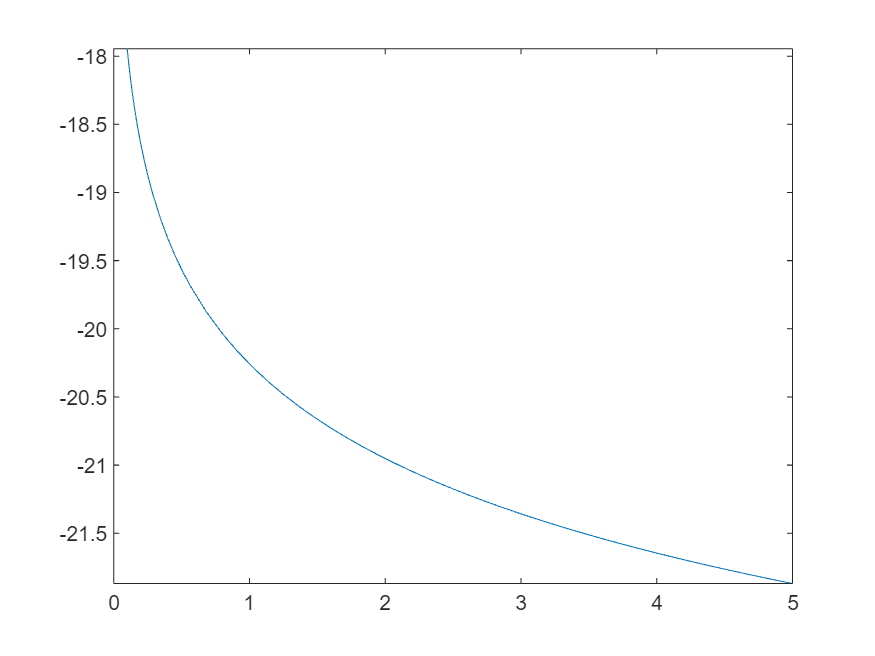

fplot(f)